clc
clear
w=windmatlab

**导入20附息国债的付息日期信息**

StartDate = datetime('20201119','InputFormat','yyyyMMdd')

StartDate = datetime
   2020-11-19



EndDate = StartDate + calyears(10)

EndDate = datetime
   2030-11-19



coupon_date = {};

d=StartDate;

i=1;

while d < EndDate
   d = d + calmonths(6);
   coupon_date(i,:) = {d};
   i = i + 1;
end

global pp sigma c t T strike

Nowadays = datetime('20210427',"InputFormat","yyyyMMdd")

Nowadays = datetime
   2021-04-27



N = datenum(Nowadays)/365

N = 2.0227e+03


T = datenum(Nowadays+calmonths(6))/365 - N

T = 0.5014


ct = coupon_date;
i = 0;
fst_cd = ct{1};

while fst_cd+calmonths(6*i) < Nowadays + calmonths(6)
    i = i + 1;
    ct(i) = [];
end

t=[];

for i = 1:size(ct,1)
    t(i,:) = datenum(ct{i})/365 - N;
end

t

t =     0.5644
    1.0603
    1.5644
    2.0603
    2.5644
    3.0630
    3.5671
    4.0630
    4.5671
    5.0630



CouponRate = 0.0327;

c = CouponRate/2*ones(size(ct));
c(size(ct,1)) = c(size(ct,1)) + 1;

**读取中债即期收益率数据**

ZeroRate = w.edb(['M1004179,M1004696,M1001099,M1001100,' ...
    'M1001101,M1001102,M1001103,M1001104,M1001105,M1001106,' ...
    'M1001107,M1001108,M1001109,M1004697,M1001110'] ...
    ,Nowadays,Nowadays)

ZeroRate =     1.5459
    1.7057
    1.9633
    2.0798
    2.3421
    2.4082
    2.7198
    2.7995
    2.9011
    3.0209


**用Cubic Spline data interpolation获得国债即期收益率曲线（零利率曲线）**

x = [0,1/12,3/12,6/12,9/12,1:1:10];
y = ZeroRate';

xx = 0:.001:10;
yy = spline(x,y,xx);

pp = spline(x,y)

pp = 包含以下字段的 struct :
      form: 'pp'
    breaks: [0 0.0833 0.2500 0.5000 0.7500 1 2 3 4 5 6 7 8 9 10]
     coefs: [14×4 double]
    pieces: 14
     order: 4
       dim: 1


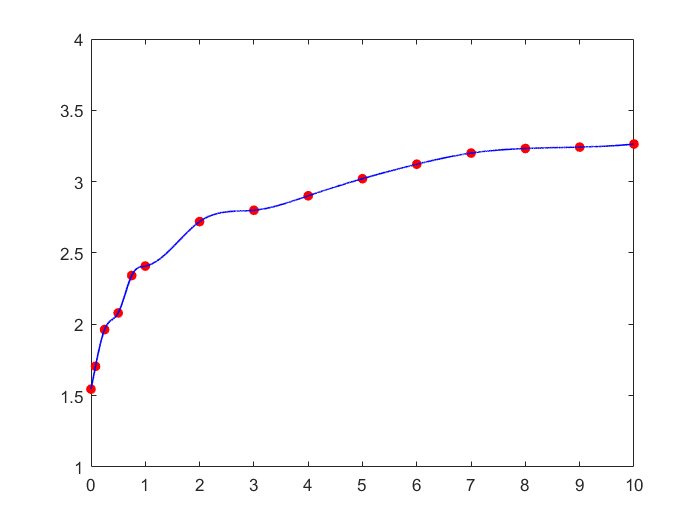

plot(x,y,'r.',xx,yy,'b-','MarkerSize',20,'LineWidth',1);
hold on

axis([0 10 1 4])

**求导得到各点上的Instantaneous Forward Rate**

x1 = 0:.5:10;
y1 = ppval(fnder(pp),x1);

IFR = ppval(pp,x1) + x1.*y1

IFR =     1.5459    2.4289    2.4746    3.1147    3.2552    2.8971    2.9097    3.2268    3.4183    3.5026    3.5720    3.6299    3.6806    3.6857    3.5902    3.4511    3.3529    3.3095    3.3332    3.4406    3.6483


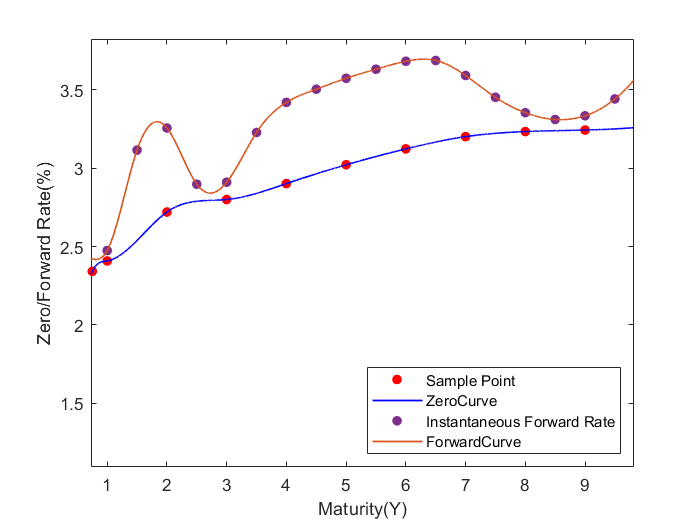


plot(x1,IFR,'LineStyle','none','Marker','.','color','#7E2F8E', ...
    'MarkerSize',20);
hold on

yy1 = spline(x1,IFR,xx);
plot(xx,yy1,'color','#D95319','LineWidth',1)
hold off

xlabel('Maturity(Y)')
ylabel('Zero/Forward Rate(%)')

legend('Sample Point','ZeroCurve','Instantaneous Forward Rate', ...
    'ForwardCurve','location','southeast')

sigma = [1.5;1.7;2]*1e-2

sigma =     0.0150
    0.0170
    0.0200



strike = 102*1e-2;

x2 = 0:.001:0.3;

y2 = kfunc(x2);

y2

y2 =     0.0432    0.0349    0.0267    0.0185    0.0105    0.0024   -0.0055   -0.0134   -0.0212   -0.0290   -0.0366   -0.0442   -0.0518   -0.0593   -0.0667   -0.0741   -0.0813   -0.0886   -0.0957   -0.1029   -0.1099   -0.1169   -0.1238   -0.1307   -0.1375   -0.1442   -0.1509   -0.1576   -0.1641   -0.1707   -0.1771   -0.1835   -0.1899   -0.1962   -0.2025   -0.2087   -0.2148   -0.2209   -0.2269   -0.2329   -0.2388   -0.2447   -0.2506   -0.2564   -0.2621   -0.2678   -0.2734   -0.2790   -0.2845   -0.2900
    0.0421    0.0338    0.0256    0.0174    0.0093    0.0013   -0.0066   -0.0145   -0.0223   -0.0300   -0.0377   -0.0453   -0.0528   -0.0603   -0.0677   -0.0751   -0.0823   -0.0896   -0.0967   -0.1038   -0.1109   -0.1178   -0.1248   -0.1316   -0.1384   -0.1452   -0.1518   -0.1585   -0.1650   -0.1716   -0.1780   -0.1844   -0.1908   -0.1971   -0.2033   -0.2095   -0.2156   -0.2217   -0.2277   -0.2337   -0.2397   -0.2455   -0.2514   -0.2571   -0.2629   -0.2686   -0.2742   -0.2798   -0.2853   -

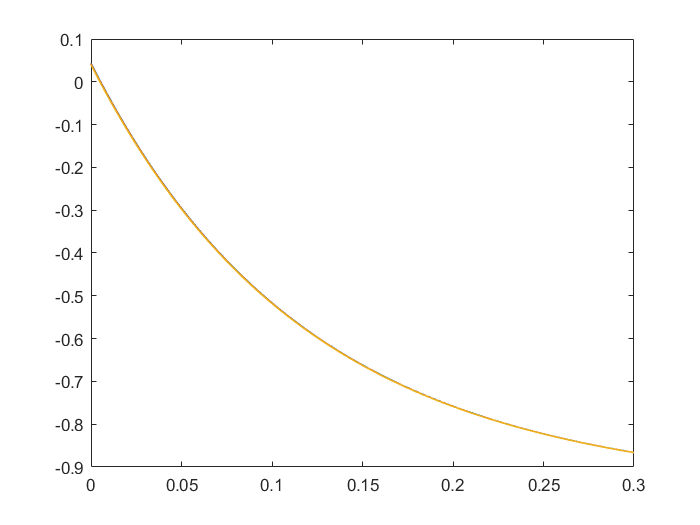


for j = 1 : size(sigma,1)
    plot(x2,y2(j,:),'LineWidth',1);
    
    if j < 3
        hold on
    else
        hold off
    end
end

syms r [1 size(sigma,1)]

r0 = 0.003

r0 = 0.0030


r_star = zeros(size(sigma'));

tic
for i = 1:size(sigma,1)
    df = diff(kfunc(r),r(i));
    kf = symfun(int(df,r(i))-strike,r(i));
    r_star(i) = NewtonIteration(kf(r(i)),r0,1e-4);
end
toc

历时 44.542790 秒。



r_star

r_star =     0.0053    0.0052    0.0049


syms rx

P = symfun(vpa(normcdf(rx)),rx);

[outputVec V] = kfunc(r_star);

for i = 1:size(sigma,1)
    KC(:,i) = V(:,i,i);
end
K = KC./(c*ones(size(sigma')));

B=zeros(size(t));
for i = 1:size(t,1)
    B(i) = zcb(t(i));
end

d1 = 1./(sqrt(T)*(t-ones(size(t))*T)*sigma').*...
(log(B/zcb(T))*ones(size(sigma'))-log(K)+T/2* ...
(t-ones(size(t))*T).^2*(sigma'.^2))

d1 =    -0.1669   -0.1586   -0.1515
   -0.1616   -0.1526   -0.1445
   -0.1563   -0.1466   -0.1373
   -0.1510   -0.1406   -0.1303
   -0.1457   -0.1345   -0.1232
   -0.1404   -0.1285   -0.1161
   -0.1350   -0.1224   -0.1090
   -0.1297   -0.1165   -0.1020
   -0.1244   -0.1104   -0.0948
   -0.1191   -0.1044   -0.0878



d2 = d1 - sqrt(T)*(t-ones(size(t))*T)*sigma'

d2 =    -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524
   -0.1676   -0.1593   -0.1524


P1 = double(P(d1));
P2 = double(P(d2));

OptionPrice = zcb(T)*c'*((B/zcb(T))*ones(size(sigma')).*P1-K.*P2)

OptionPrice =     0.0284    0.0328    0.0394
